clc;
clear;
close;
load('analysis.mat');
load('intervals.mat');
load('footOff_indices.mat');

- join all hip, knee, ankle angles together in 3 plots

- do the same for the mean() with 2std

- create a hyriarchy from most to least noise

-     off -> myoMotion -> light -> moderate 

-     where myomotion should not be noisy, rather our refSignal

-     set colors for those graphs (off 'r'), (myoMotion 'g'), (light 'o'), (moderate 'b')

## find mean graphs

## Hip Normalized                                      

fig = figure("Name","left normalized vs right mean2std","PaperSize",[21 29.7]);
sgtitle("left normalized vs right mean2std")
subplot(3,2,1); 
%Start with HIP-ANG
plot(analysis.off.RT.HipFlexion,'r.-','LineWidth',0.25);
% axis([0 100 -20 35]);
xlabel("gait cycle in %");
ylabel("angle in [deg]");
grid on;
title("Hip");
hold on;
%myoMotionData is not included inside
%plot(analysis.myoMotion.RT.HipFlexion,'g');
plot(analysis.light.RT.HipFlexion,'y.-','LineWidth',0.25);
plot(analysis.moderate.RT.HipFlexion,'c.-','LineWidth',0.25);
hold off;

## Hip Normalized  - Mean2std

subplot(3,2,2); %Start with HIP-ANG
plot(analysis.off.RT.HipMean,'r.-','LineWidth',0.25);
title("Hip");
% axis([0 100 -20 35]);
xlabel("gait cycle in %");
ylabel("angle in [deg]");
grid on;
hold on;
%myoMotionData is not included inside
%plot(analysis.myoMotion.RT.HipFlexion,'g');
plot(analysis.light.RT.HipMean,'y.-','LineWidth',0.25);
plot(analysis.moderate.RT.HipMean,'c.-','LineWidth',0.25);
hold off;

## Knee Normalized  

subplot(3,2,3); %KneeFlexion
plot(analysis.off.RT.KneeFlexion,'r.-','LineWidth',0.25);
title("Knee");
% axis([0 100 -10 80]);
xlabel("gait cycle in %");
ylabel("angle in [deg]");
grid on;
hold on;
%myoMotionData is not included inside
%plot(analysis.myoMotion.RT.KneeFlexion,'g');
plot(analysis.light.RT.KneeFlexion,'y.-','LineWidth',0.25);
plot(analysis.moderate.RT.KneeFlexion,'c.-','LineWidth',0.25);
hold off;

## Knee Normalized  - Mean2std

subplot(3,2,4); %Start with HIP-ANG
plot(analysis.off.RT.KneeMean,'r.-','LineWidth',0.25);
title("Knee");
% axis([0 100 -10 80]);
xlabel("gait cycle in %");
ylabel("angle in [deg]");
grid on;
hold on;
%myoMotionData is not included inside
%plot(analysis.myoMotion.RT.HipFlexion,'g');
plot(analysis.light.RT.KneeMean,'y.-','LineWidth',0.25);
plot(analysis.moderate.RT.KneeMean,'c.-','LineWidth',0.25);
hold off;

## Ankle Normalized

subplot(3,2,5); %KneeFlexion
plot(analysis.off.RT.AnkleDorsiflexion,'r.-','LineWidth',0.25);
% axis([0 100 -30 25]);
title("Ankle");
xlabel("gait cycle in %");
ylabel("angle in [deg]");
grid on;
hold on;
%myoMotionData is not included inside
%plot(analysis.myoMotion.RT.KneeFlexion,'g');
plot(analysis.light.RT.AnkleDorsiflexion,'y.-','LineWidth',0.25);
plot(analysis.moderate.RT.AnkleDorsiflexion,'c.-','LineWidth',0.25);
hold off;

## Ankle Normalized  - Mean2std

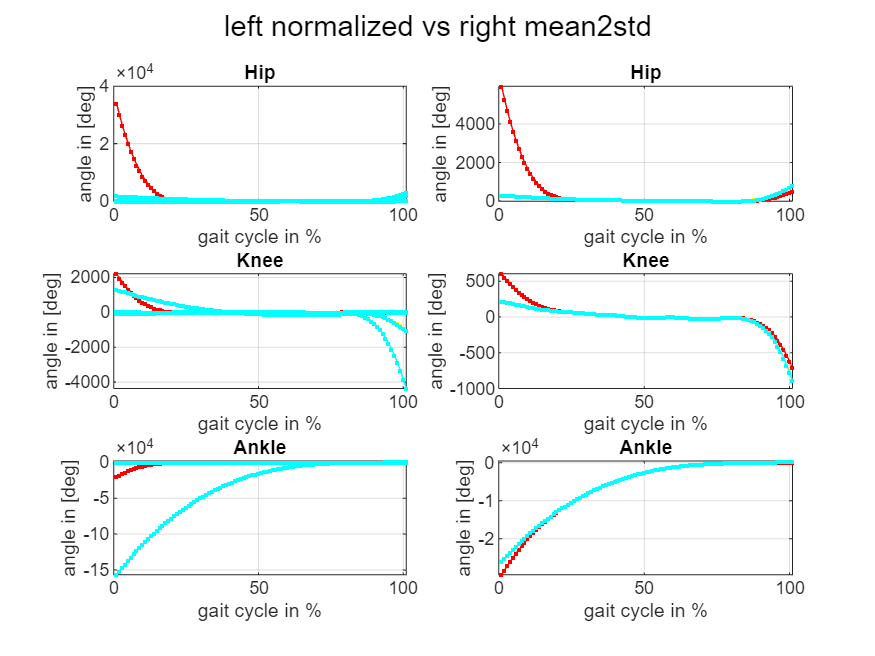

subplot(3,2,6); %Start with HIP-ANG
plot(analysis.off.RT.AnkleMean,'r.-','LineWidth',0.25);
title("Ankle");
% axis([0 100 -30 25]);
xlabel("gait cycle in %");
ylabel("angle in [deg]");
grid on;
hold on;
%myoMotionData is not included inside
%plot(analysis.myoMotion.RT.AnkleMean,'g');
plot(analysis.light.RT.AnkleMean,'y.-','LineWidth',0.25);
plot(analysis.moderate.RT.AnkleMean,'c.-','LineWidth',0.25);
hold off;
print('comparisonPic','-dsvg');

% print('comparisonPic2','-dpfd')



## Test02

% [test1, test2] = normalizeAndPlot(analysis.off.RT.HipFlexion,intervals,footOff_indices);
% figure;
% plot(test1)
% hold on;
% % plot(test2);
% plot(analysis.off.RT.HipFlexion);
% hold off